🔄 Running the pipeline to compute results...

🚀 Training Wide Component...
🚀 Training Wide Component...
Epoch 001 | TrainLoss: 0.1026 | ValLoss: 0.1348 | Acc: 0.6300 | F1: 0.0513 | Neurons: 15 | LR: 0.01000
Epoch 002 | TrainLoss: 0.1239 | ValLoss: 0.1159 | Acc: 0.6950 | F1: 0.1159 | Neurons: 15 | LR: 0.01000
📈 Added neurons: 20 total neurons now
Epoch 003 | TrainLoss: 0.1089 | ValLoss: 0.1198 | Acc: 0.6650 | F1: 0.2472 | Neurons: 20 | LR: 0.01000
Epoch 004 | TrainLoss: 0.1348 | ValLoss: 0.1065 | Acc: 0.6600 | F1: 0.2093 | Neurons: 20 | LR: 0.01000
📈 Added neurons: 25 total neurons now
Epoch 005 | TrainLoss: 0.1057 | ValLoss: 0.1225 | Acc: 0.6550 | F1: 0.2247 | Neurons: 25 | LR: 0.01000
Epoch 006 | TrainLoss: 0.1372 | ValLoss: 0.1048 | Acc: 0.7050 | F1: 0.2338 | Neurons: 25 | LR: 0.01000
📈 Added neurons: 30 total neurons now
Epoch 007 | TrainLoss: 0.1098 | ValLoss: 0.1445 | Acc: 0.5950 | F1: 0.0690 | Neurons: 30 | LR: 0.01000
Epoch 008 | TrainLoss: 0.1486 | ValLoss: 0.1091 | Acc: 0.6350

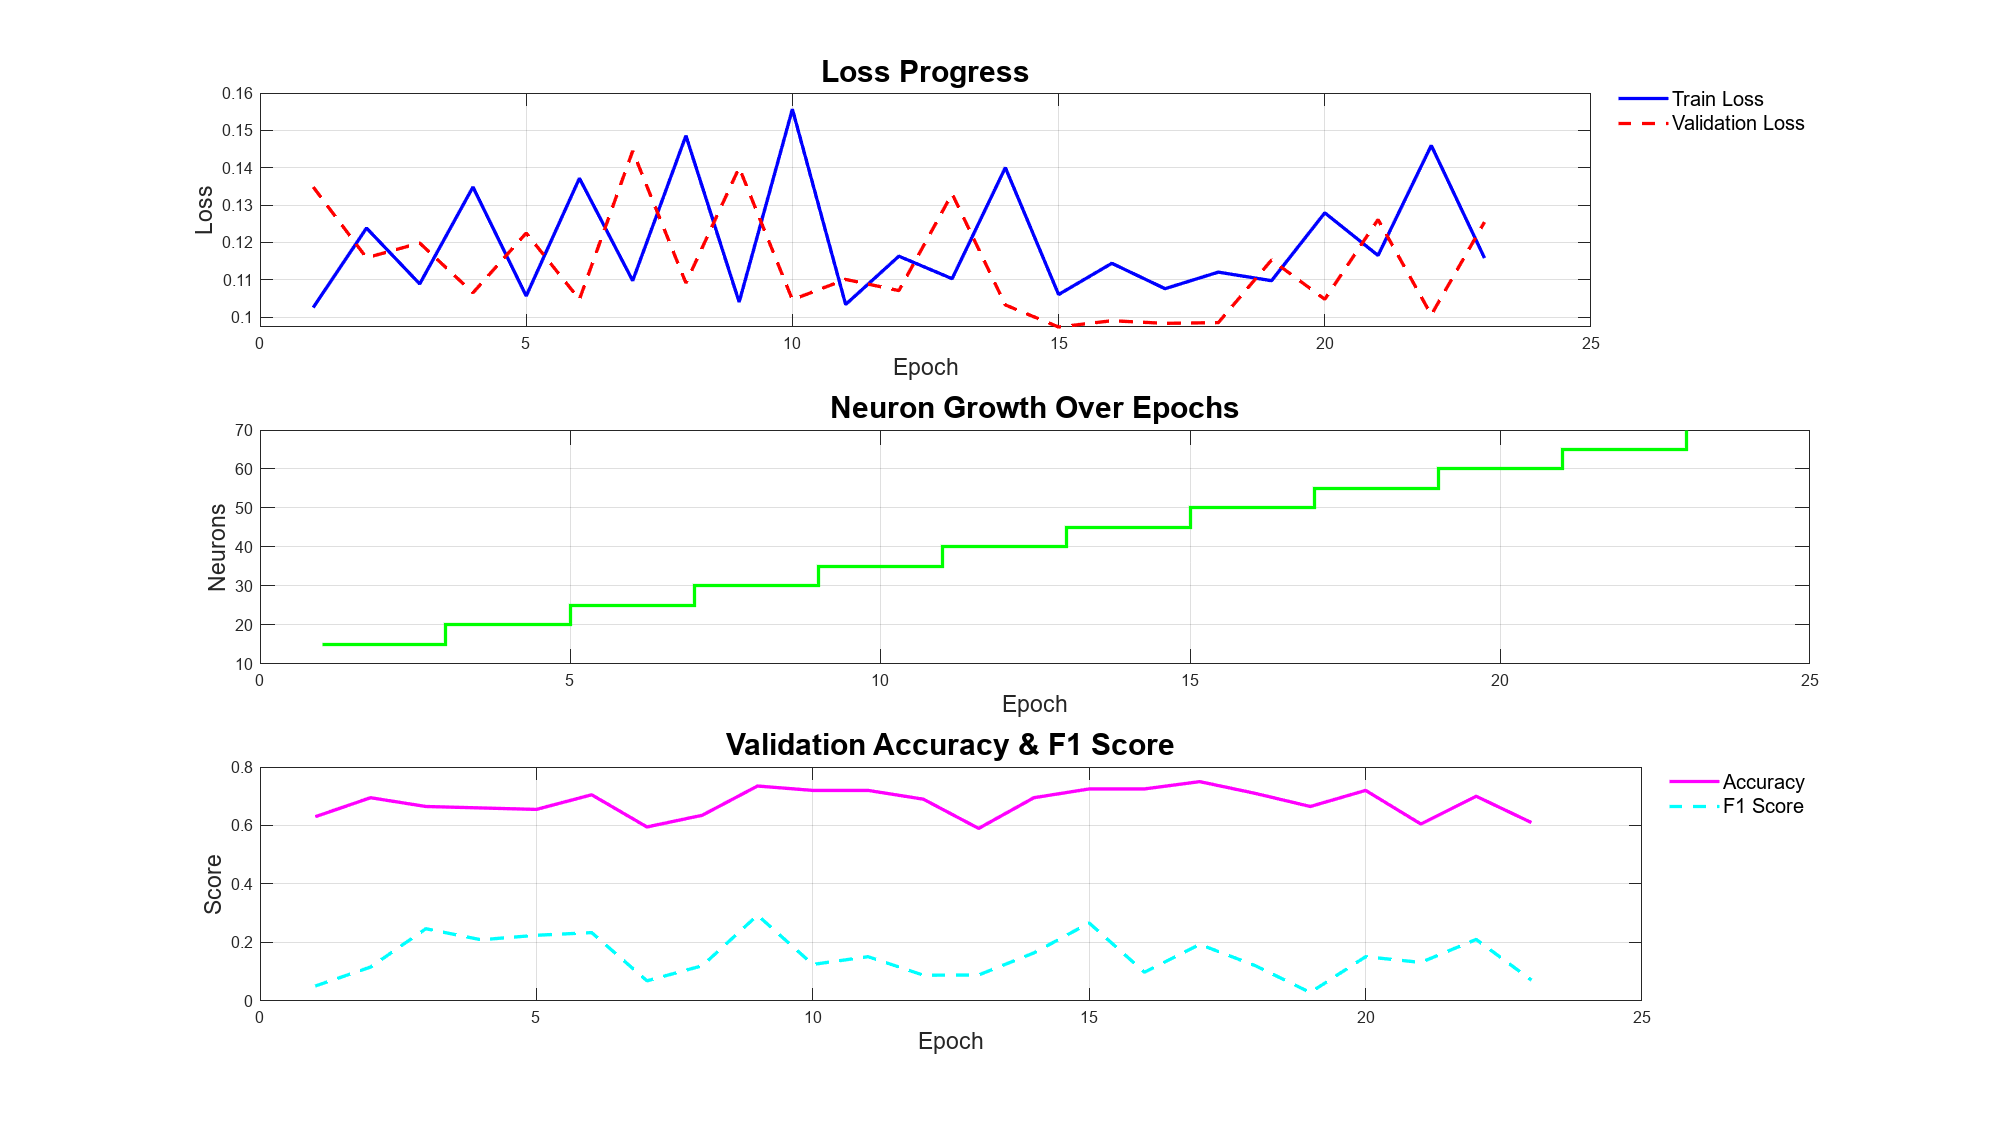

✅ Wide output saved to "wide_output_features.csv" with size [50 × 1000].

🚀 Training Deep Component...
🚀 Training Deep Component...
Epoch 01 - Loss: 2.5189 - Acc: 84.70% - Filters: 12
Epoch 02 - Loss: 1.1169 - Acc: 79.80% - Filters: 12
Epoch 03 - Loss: 0.8310 - Acc: 91.00% - Filters: 12
Epoch 04 - Loss: 0.6382 - Acc: 91.00% - Filters: 12
Epoch 05 - Loss: 0.5652 - Acc: 91.00% - Filters: 12
Epoch 06 - Loss: 0.5649 - Acc: 91.00% - Filters: 12
Epoch 07 - Loss: 0.5532 - Acc: 91.00% - Filters: 12
Epoch 08 - Loss: 0.5463 - Acc: 91.00% - Filters: 12
Epoch 09 - Loss: 0.5413 - Acc: 91.00% - Filters: 12
Epoch 10 - Loss: 0.5410 - Acc: 91.00% - Filters: 12
Epoch 11 - Loss: 0.5391 - Acc: 91.00% - Filters: 12
Epoch 12 - Loss: 0.5333 - Acc: 91.00% - Filters: 12
Epoch 13 - Loss: 0.5343 - Acc: 91.00% - Filters: 12
📈 Growing filters to 16
Epoch 14 - Loss: 2.6570 - Acc: 85.80% - Filters: 16
📈 Growing filters to 20
Epoch 15 - Loss: 2.6918 - Acc: 86.90% - Filters: 20
📈 Growing filters to 24
Epoch 16 - Loss:

allModels = 9×4 cell array
    {'TSR (1)'                }    {[0.5705]}    {[0.5056]}    {[0.5140]}
    {'TSR (2)'                }    {[0.5903]}    {[0.5755]}    {[0.5577]}
    {'LR (Logistic)'          }    {[0.6773]}    {[0.6442]}    {[0.5669]}
    {'SVM'                    }    {[0.7183]}    {[0.6862]}    {[0.5919]}
    {'RF'                     }    {[0.7317]}    {[0.9078]}    {[0.8670]}
    {'Wide'                   }    {[0.6751]}    {[0.8013]}    {[0.7675]}
    {'CNN'                    }    {[0.7636]}    {[0.9059]}    {[0.8835]}
    {'Wide & Deep CNN (paper)'}    {[0.7760]}    {[0.9404]}    {[0.8961]}
    {'Wide & Deep CNN (yours)'}    {[     1]}    {[     1]}    {[     1]}


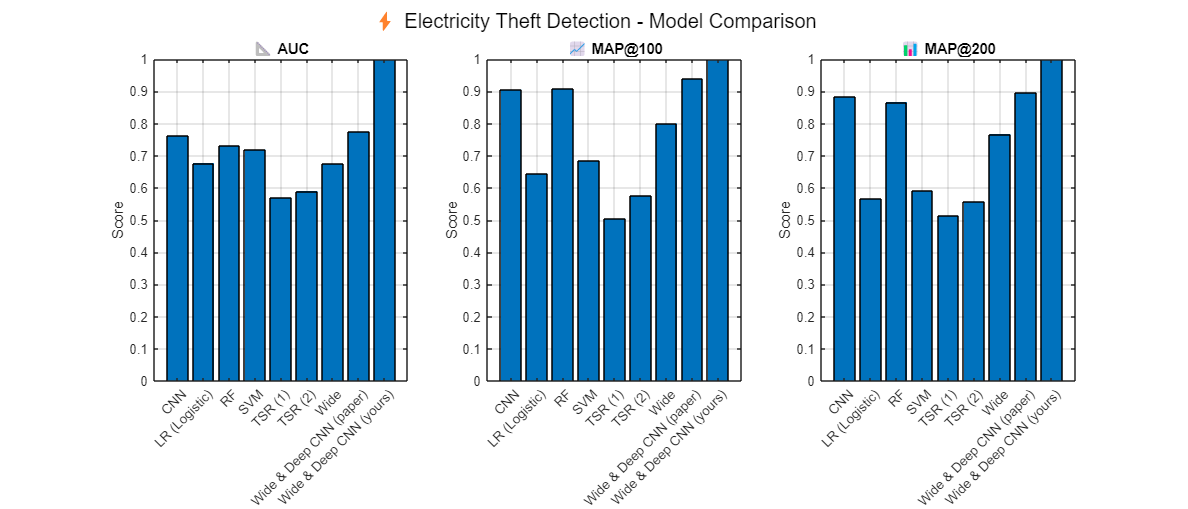


✅ DeepWide Model Evaluation Complete:
   - AUC      : 1.0000
   - MAP@100  : 1.0000
   - MAP@200  : 1.0000


% Add the path to your custom functions (make sure this path is correct)
addpath('G:\PhD\area of investigation\TASKS\the original chinees paper\Matlab_Code\shortcut_git\functions');

% === Step 1: Load your data ===
sampledData = readtable('G:\PhD\area of investigation\TASKS\the original chinees paper\Matlab_Code\shortcut_git\sampled_healthy_customers.csv', 'VariableNamingRule', 'preserve');

% === Step 2: Define training configuration (optional) ===
config = struct();
config.wideLR = 0.01;
config.wideNeurons = 15;
config.deepLR = 0.01;
config.deepFilters = 12;
config.patience = 8;
config.l2Lambda = 1e-4;

% === Step 3: Train the full model ===
forceRecompute = true; % Set to true to recompute results
results = trainWideAndDeepEndToEnd(sampledData, config, forceRecompute);